# Impact of IOs, IWs, and tides and on the different metrics considered in this study.

Here we study the impact of wave like motions, which do no lead to any particle dispersion, on the different metrics considered here.

In particular, we try to look at the impact that changing the shape in the wavenumber spectrum of these waves has. There is no theory for how the IWs motions are shaped in wavenumber space. 

clear all
close all 

% load some model data 
d = 10; 

distance = [10,15]*1e3;

i = 1; 
[mod_traj(i).X, mod_traj(i).Y, mod_traj(i).U, mod_traj(i).V, mod_traj(i).T, depth(i)] = loadpairs(d(i));

depth = -1.4749e+03

    
% get the velocity from forward differencing (will be important for structure functions)
Unew = nan*mod_traj(i).X;
Vnew = nan*mod_traj(i).X;
dt = 1*24*3600; 
cor = 110*1e3; 

Unew(1:end-1,:) = diff(mod_traj(i).X)*cor.*cosd(mod_traj(i).Y(1:end-1,:))/dt; 
Vnew(1:end-1,:) = diff(mod_traj(i).Y)*cor/dt; 

mod_traj(i).U = Unew; 
mod_traj(i).V = Vnew; 

mod_traj(i).U(mod_traj(i).U==-999) = NaN;
mod_traj(i).V(mod_traj(i).V==-999) = NaN;
mod_traj(i).Y(mod_traj(i).X>360-70) = NaN;
mod_traj(i).U(mod_traj(i).X>360-70) = NaN;
mod_traj(i).V(mod_traj(i).X>360-70) = NaN;
mod_traj(i).X(mod_traj(i).X>360-70) = NaN;

## Add IOs with different props

We will consider adding a model of the kind

x_i -> A(sinft, cosft-1)

x_j -> (A+B g(t))(sinft, cosft-1)

where A is a random number, and B is also a random number. A is representative of the radius of the inertial oscialltions, but is same for both the floats in a pair. B g(t) models the growing difference in radius of IOs as the floats in a pair separate. 

g(t) is a function of time, which is 0 at t=0 and 1 at large t. Here we chose to model this as (1-exp(-ct)). This is an arbitrary choice, since we don't actually know what this function looks like. When g(t) is zero both particles move in the same IOs, and have no relative motion in the IO frequency. When g(t) is 1 the particles move relative to each other with in a circle with radius B. 

We can also set g( r), instead of a function of time and see the impact it has. Setting it as a function of separation provides more control on the spatial spectrum. 

f = 2*2*pi/(1)*sind(-55); % in units of per day

%% 
X =mod_traj.X; 
Y =mod_traj.Y; 
%% Interpolate to hourly
T = 0:735; 
Tint = 0:1/24:735;
   
Xint = interp1(T, X, Tint, 'linear'); 
Yint = interp1(T, Y, Tint, 'linear'); 

mod_traj_int.X = Xint;
mod_traj_int.Y = Yint;
mod_traj_int.T = Tint';

mod_sep_orig_orig = model_sep_calcs(mod_traj, distance);

mod_sep_orig = model_sep_calcs_w_NIWs(mod_traj, distance, f, 0,0,0,0);
%
% modint_sep_orig = model_sep_calcs_w_NIWs(mod_traj_int, distance, f, 0,0,0,0);

% Add IOs with temporally changing IOs
% A = radius of IOs (degrees) 
% B = relative radius of IOs (degrees)
% C = decorrelation rate (1/days) 

mod_sep_time1 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110,2/110, 1/20, 1);
mod_sep_time2 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110,4/110, 1/20, 1);
mod_sep_time3 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110,2/110, 1/40, 1);
mod_sep_time4 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 4/110,2/110, 1/20, 1);

modint_sep_time1 = model_sep_calcs_w_NIWs(mod_traj_int, distance, f, 2/110,2/110, 1/20, 1);

% Add IOs with spatially changing IOs
% A = radius of IOs (degrees) 
% B = relative radius of IOs (degrees)
% C = power law behavior of IO radius as a function of space
% If we want the largest difference in relative IOs to be X, then we set B
% = X/(r_l^C), where r_L = 100e3. 
% so if X = 2/110, when a=2/3, then B = (2/110)/(100e3^(2/3)) = 8.5e-6

mod_sep_space1 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110, (2/110)/(100e3^(2/3)), 2/3, 2);
mod_sep_space2 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110, (2/110)/(100e3^(1)), 1, 2);
mod_sep_space3 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110, (2/110)/(100e3^(2)), 2, 2);
mod_sep_space4 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110, (4/110)/(100e3^(2/3)), 2/3, 2);
mod_sep_space5 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110, (8/110)/(100e3^(2/3)), 2/3, 2);
mod_sep_space6 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110, (3/110)/(100e3^(1/3)), 1/3, 2);

mod_sep_space7 = model_sep_calcs_w_NIWs(mod_traj, distance, f, 2/110, (5/110)/(100e3^(2/3)), 2/3, 3);

Not enough input arguments.

Error in model_sep_calcs_w_NIWs (line 81)
        id1 = find(separation<L);

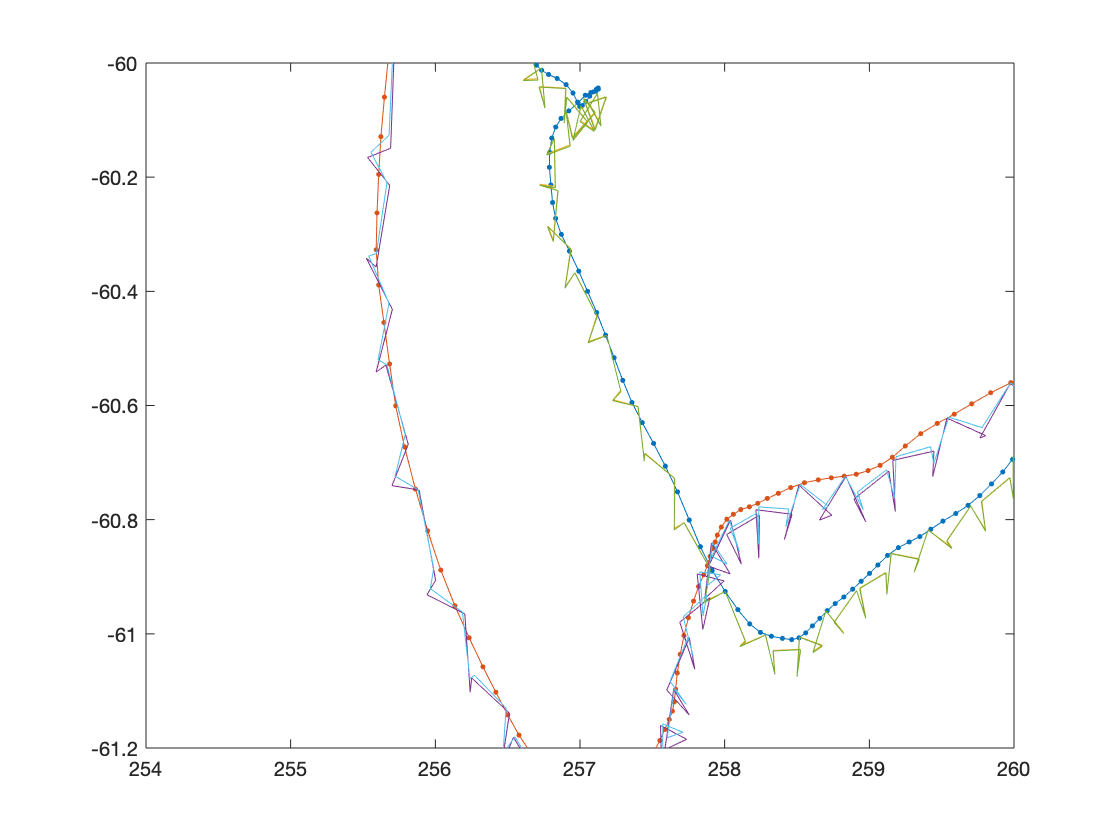

% Plot some trajectories to see what adding the IOs does
figure
n=50;
plot(mod_sep_orig.sep(n).X1, mod_sep_orig.sep(n).Y1, '.-')
hold all
plot(mod_sep_orig.sep(n).X2, mod_sep_orig.sep(n).Y2, '.-')

plot(mod_sep_time1.sep(n).X1, mod_sep_time1.sep(n).Y1)
plot(mod_sep_time1.sep(n).X2, mod_sep_time1.sep(n).Y2)

plot(mod_sep_space1.sep(n).X1, mod_sep_space1.sep(n).Y1)
plot(mod_sep_space1.sep(n).X2, mod_sep_space1.sep(n).Y2)

axis([254 260 -61.2 -60])

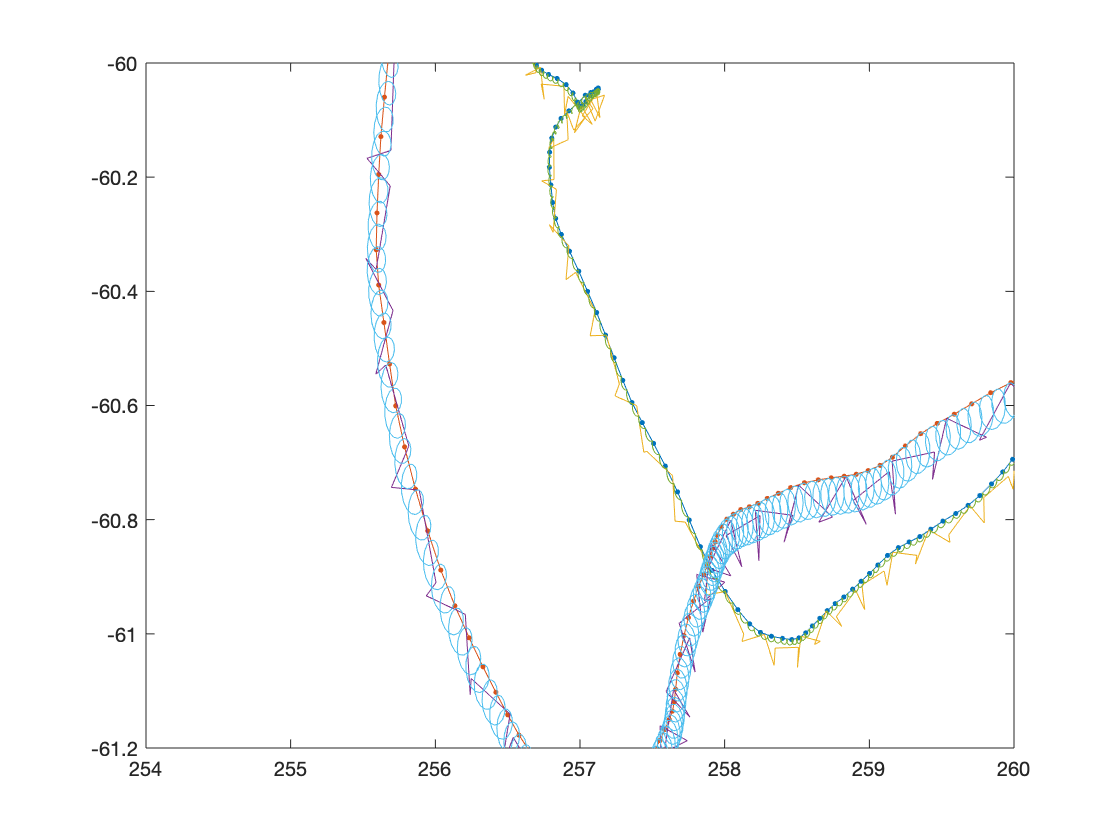

% Plot some trajectories to see what adding the IOs does
figure
n=50;
plot(mod_sep_orig.sep(n).X1, mod_sep_orig.sep(n).Y1, '.-')
hold all
plot(mod_sep_orig.sep(n).X2, mod_sep_orig.sep(n).Y2, '.-')

plot(mod_sep_time1.sep(n).X1, mod_sep_time1.sep(n).Y1)
plot(mod_sep_time1.sep(n).X2, mod_sep_time1.sep(n).Y2)

plot(modint_sep_time1.sep(n).X1, modint_sep_time1.sep(n).Y1)
plot(modint_sep_time1.sep(n).X2, modint_sep_time1.sep(n).Y2)

axis([254 260 -61.2 -60])

%% first define the distance axis 
gamma = 1.4;
dist_bin(1) = 1000; % in m
dist_bin = gamma.^(0:100)*dist_bin(1);
id = find(dist_bin>800*10^3,1);
dist_bin = dist_bin(1:id);
dist_bin(2:end+1) = dist_bin(1:end);
dist_bin(1) = 0;
dist_axis = 0.5*(dist_bin(1:end-1) + dist_bin(2:end));

flag_1time = 1;

## Check if the right spatial pattern has been imposed on IOs

for i =1:length(mod_sep_orig.sep)
    dr(:,i) = abs(mod_sep_orig.sep(i).dist - mod_sep_time1.sep(i).dist);
    dr1(:,i) = abs(mod_sep_orig.sep(i).dist - mod_sep_space1.sep(i).dist);
    dr2(:,i) = abs(mod_sep_orig.sep(i).dist - mod_sep_space2.sep(i).dist);
    dr3(:,i) = abs(mod_sep_orig.sep(i).dist - mod_sep_space3.sep(i).dist);
    dr4(:,i) = abs(mod_sep_orig.sep(i).dist - mod_sep_space4.sep(i).dist);
    dr7(:,i) = abs(mod_sep_orig.sep(i).dist - mod_sep_space7.sep(i).dist);
    r(:,i) = mod_sep_orig.sep(i).dist;
end

Unable to resolve the name mod_sep_space7.sep.


for i = 1:length(dist_axis)
    id = find(r>=dist_bin(i) & r<dist_bin(i+1));
    
    drmean(i) = nanmean(dr(id));
    dr1mean(i) = nanmean(dr1(id));
    dr2mean(i) = nanmean(dr2(id));
    dr3mean(i) = nanmean(dr3(id));
    dr4mean(i) = nanmean(dr4(id));
    
    dr7mean(i) = nanmean(dr7(id));

end

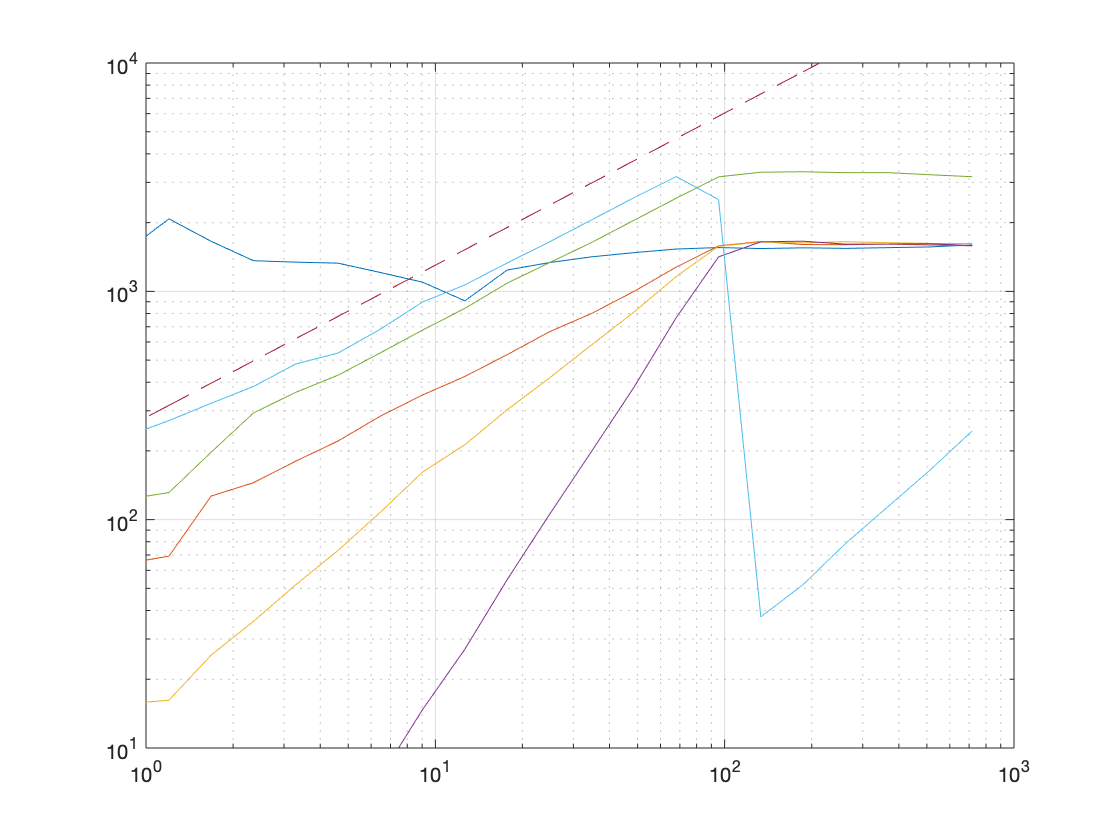

% Plot of spatial dependence of relative magniture
figure
loglog(dist_axis/1e3, drmean )
hold all
loglog(dist_axis/1e3, dr1mean)
loglog(dist_axis/1e3, dr2mean)
loglog(dist_axis/1e3, dr3mean)
loglog(dist_axis/1e3, dr4mean)
loglog(dist_axis/1e3, dr7mean)

%loglog(dist_axis/1e3, 0.5*1e3*(4*(1-exp(-1/15e3*dist_axis))))
%loglog(dist_axis/1e3, 0.5*1e3*(6*((1/35e3*dist_axis).^(1/2))))
loglog(dist_axis/1e3, 0.5*1e3*(6*((1/35e3*dist_axis).^(2/3))),'--')
%loglog(dist_axis/1e3, 0.5*1e3*(2 + 4*(1-exp(-(1/15e3*dist_axis).^2))))

axis([1 1000 10 1e4])
grid

## FSLE

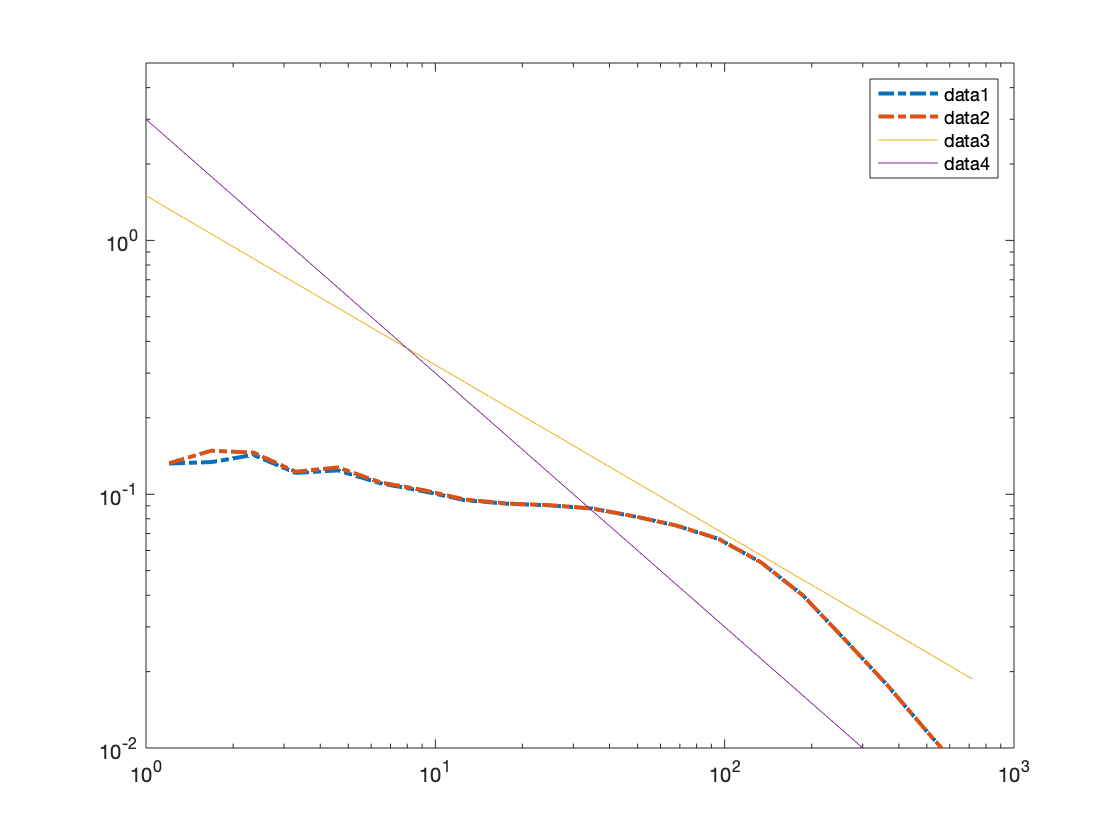


%% FSLE Orig
fsle_mod_orig = fsle_model(mod_sep_orig.sep, dist_bin, 1, flag_1time); 
%fsle_modint_orig = fsle_model(modint_sep_orig.sep, dist_bin, 1, flag_1time); 

% FSLE for time model
fsle_mod_time1 = fsle_model(mod_sep_time1.sep, dist_bin, 1, flag_1time); 
fsle_mod_time2 = fsle_model(mod_sep_time2.sep, dist_bin, 1, flag_1time);
fsle_mod_time3 = fsle_model(mod_sep_time3.sep, dist_bin, 1, flag_1time);
fsle_mod_time4 = fsle_model(mod_sep_time4.sep, dist_bin, 1, flag_1time);

% FSLE for space model
fsle_mod_space1 = fsle_model(mod_sep_space1.sep, dist_bin, 1, flag_1time); 
fsle_mod_space2 = fsle_model(mod_sep_space2.sep, dist_bin, 1, flag_1time);
fsle_mod_space3 = fsle_model(mod_sep_space3.sep, dist_bin, 1, flag_1time);
fsle_mod_space4 = fsle_model(mod_sep_space4.sep, dist_bin, 1, flag_1time);
fsle_mod_space5 = fsle_model(mod_sep_space5.sep, dist_bin, 1, flag_1time);
fsle_mod_space6 = fsle_model(mod_sep_space6.sep, dist_bin, 1, flag_1time);

fsle_mod_space7 = fsle_model(mod_sep_space7.sep, dist_bin, 1, flag_1time);

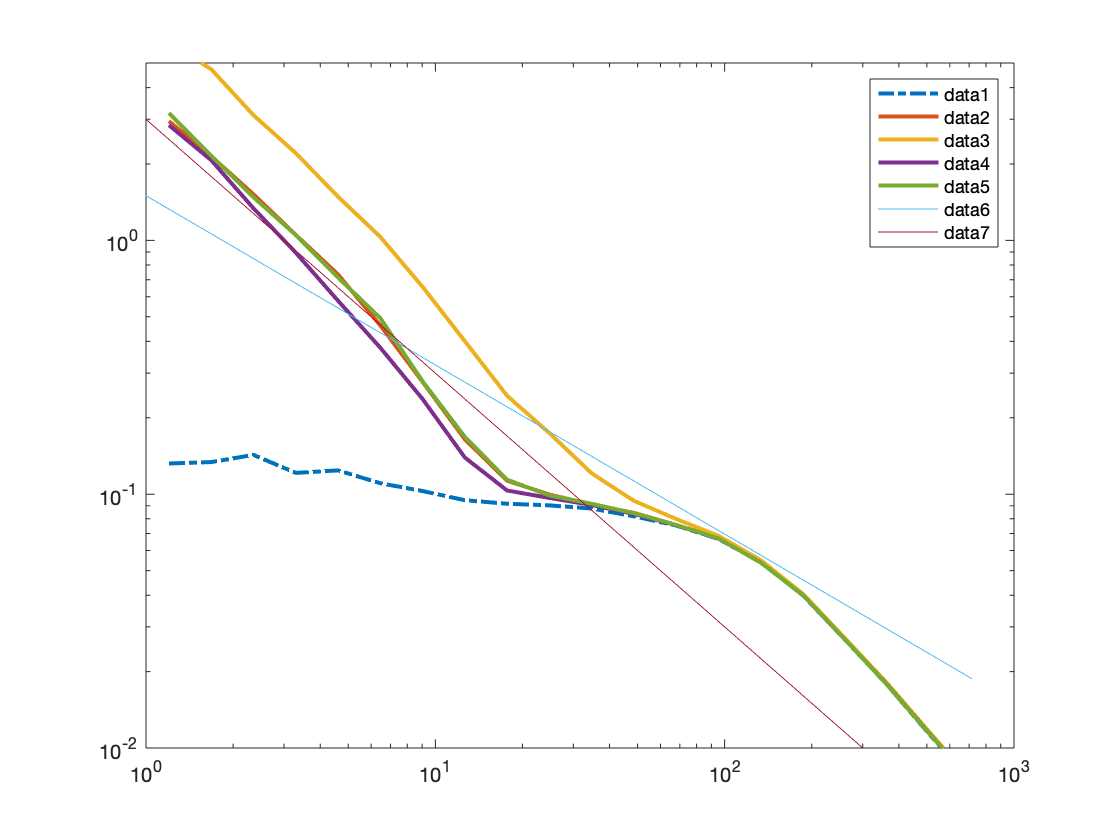

% FSLE plot for time model
figure
loglog(dist_axis/1e3, fsle_mod_orig, '-.', 'linewidth',2);
hold all 
loglog(dist_axis/1e3, fsle_mod_time1, '-', 'linewidth',2);
loglog(dist_axis/1e3, fsle_mod_time2, '-', 'linewidth',2);
loglog(dist_axis/1e3, fsle_mod_time3, '-', 'linewidth',2);
loglog(dist_axis/1e3, fsle_mod_time4, '-', 'linewidth',2);


loglog(dist_axis/1e3, 150*dist_axis.^(-2/3))
loglog(dist_axis/1e3, 3000*dist_axis.^(-1))
legend
axis([1 1000 1e-2 5])

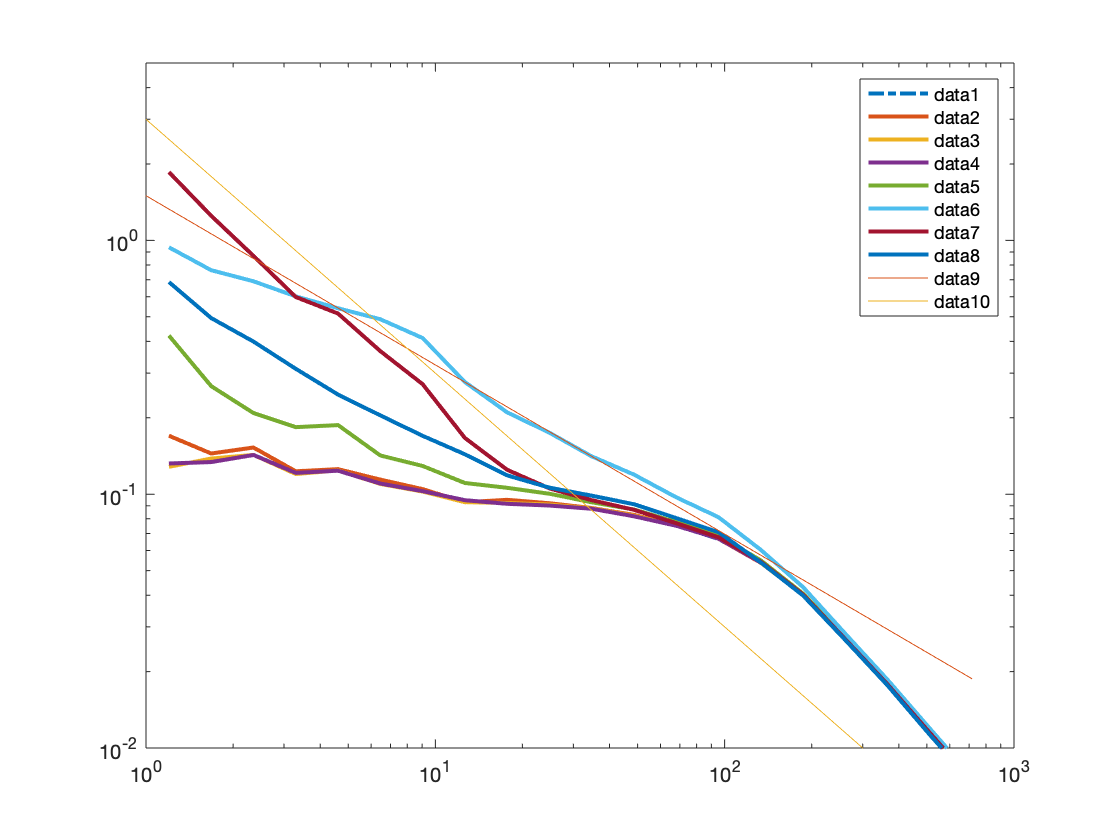

% FSLE plot for space
figure
loglog(dist_axis/1e3, fsle_mod_orig, '-.', 'linewidth',2);
hold all 
loglog(dist_axis/1e3, fsle_mod_space1, '-', 'linewidth',2);
loglog(dist_axis/1e3, fsle_mod_space2, '-', 'linewidth',2);
loglog(dist_axis/1e3, fsle_mod_space3, '-', 'linewidth',2);
loglog(dist_axis/1e3, fsle_mod_space4, '-', 'linewidth',2);
loglog(dist_axis/1e3, fsle_mod_space5, '-', 'linewidth',2);
loglog(dist_axis/1e3, fsle_mod_space6, '-', 'linewidth',2);

loglog(dist_axis/1e3, fsle_mod_space7, '-', 'linewidth',2);

loglog(dist_axis/1e3, 150*dist_axis.^(-2/3))
loglog(dist_axis/1e3, 3000*dist_axis.^(-1))
legend
axis([1 1000 1e-2 5])


% Adding IOs that have spatial variation shallower than r^(2/3) seem to
% have little impact 

## Frequency Spectrum

[F_orig, SPP_orig, SNN_orig, SPN_orig] = spec_pairs(mod_sep_orig,1);

SLEPTAP calculating tapers of length 120.


[F_time1, SPP_time1, SNN_time1, SPN_time1] = spec_pairs(mod_sep_time1,1);

SLEPTAP calculating tapers of length 120.


[F_time2, SPP_time2, SNN_time2, SPN_time2] = spec_pairs(mod_sep_time2,1);

SLEPTAP calculating tapers of length 120.


[F_time3, SPP_time3, SNN_time3, SPN_time3] = spec_pairs(mod_sep_time3,1);

SLEPTAP calculating tapers of length 120.


[F_time4, SPP_time4, SNN_time4, SPN_time4] = spec_pairs(mod_sep_time4,1);

SLEPTAP calculating tapers of length 120.


[Fint_time1, SPPint_time1, SNNint_time1, SPNint_time1] = spec_pairs(modint_sep_time1, 1/24);

SLEPTAP calculating tapers of length 512.
SLEPTAP interpolating to length 2880.


[F_space1, SPP_space1, SNN_space1, SPN_space1] = spec_pairs(mod_sep_space1,1);

SLEPTAP calculating tapers of length 120.


[F_space2, SPP_space2, SNN_space2, SPN_space2] = spec_pairs(mod_sep_space2,1);

SLEPTAP calculating tapers of length 120.


[F_space3, SPP_space3, SNN_space3, SPN_space3] = spec_pairs(mod_sep_space3,1);

SLEPTAP calculating tapers of length 120.


[F_space4, SPP_space4, SNN_space4, SPN_space4] = spec_pairs(mod_sep_space4,1);

SLEPTAP calculating tapers of length 120.


[F_space5, SPP_space5, SNN_space5, SPN_space5] = spec_pairs(mod_sep_space5,1);

SLEPTAP calculating tapers of length 120.


[F_space6, SPP_space6, SNN_space6, SPN_space6] = spec_pairs(mod_sep_space6,1);

SLEPTAP calculating tapers of length 120.


[F_space7, SPP_space7, SNN_space7, SPN_space7] = spec_pairs(mod_sep_space7,1);

SLEPTAP calculating tapers of length 120.


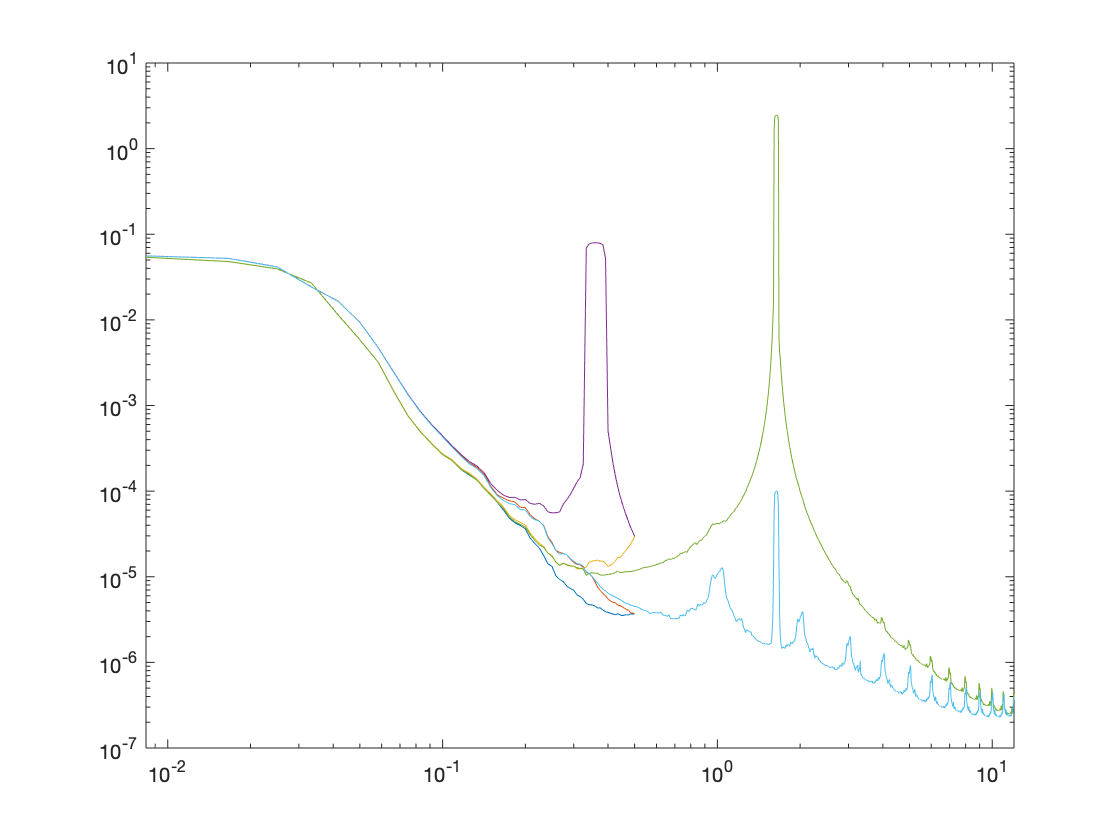

figure
loglog(F_orig, nanmean(SPP_orig,2))
hold all
loglog(F_orig, nanmean(SNN_orig,2))
loglog(F_time1, nanmean(SPP_time1,2))
loglog(F_time1, nanmean(SNN_time1,2))
loglog(Fint_time1, nanmean(SPPint_time1,2))
loglog(Fint_time1, nanmean(SNNint_time1,2))

% Since we are working with a particular frequency, a lot of the signal
% gets aliased onto lower frequencies

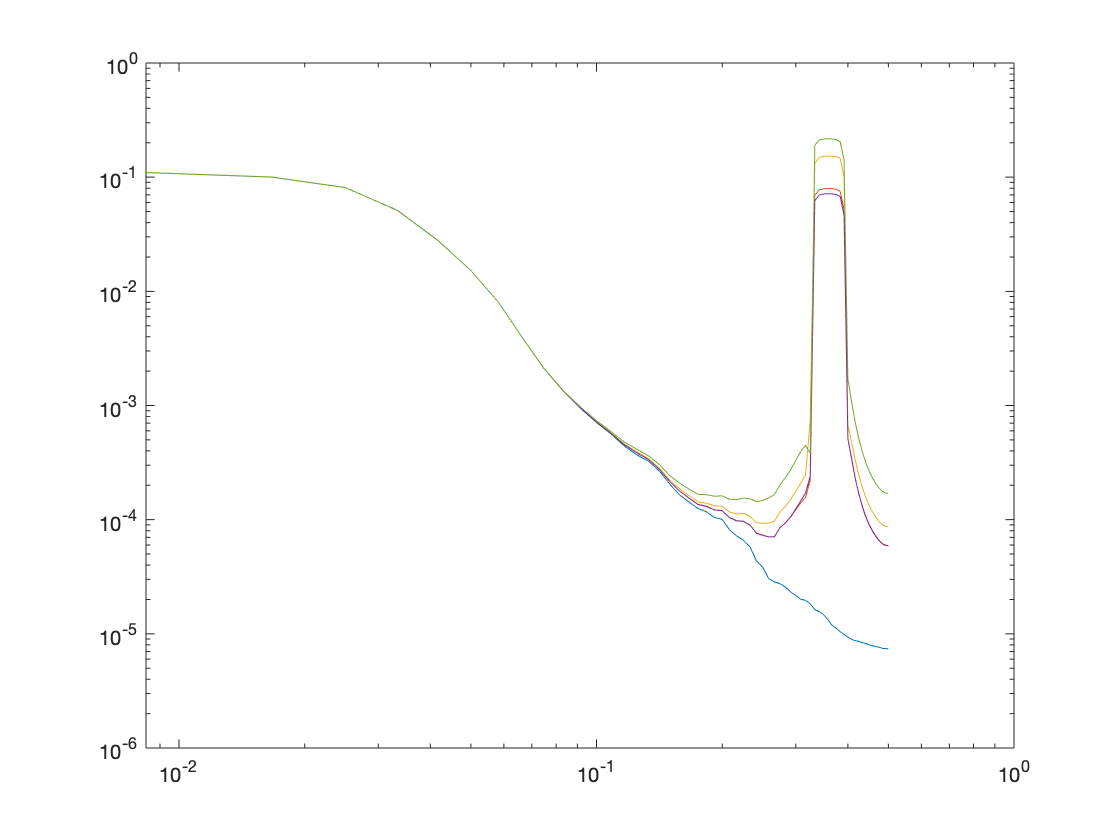

figure, 
loglog(F_orig, nanmean(SPP_orig + SNN_orig,2))
hold all 
loglog(F_orig, nanmean(SPP_time1 + SNN_time1,2))
loglog(F_orig, nanmean(SPP_time2 + SNN_time2,2))
loglog(F_orig, nanmean(SPP_time3 + SNN_time3,2))
loglog(F_orig, nanmean(SPP_time4 + SNN_time4,2))

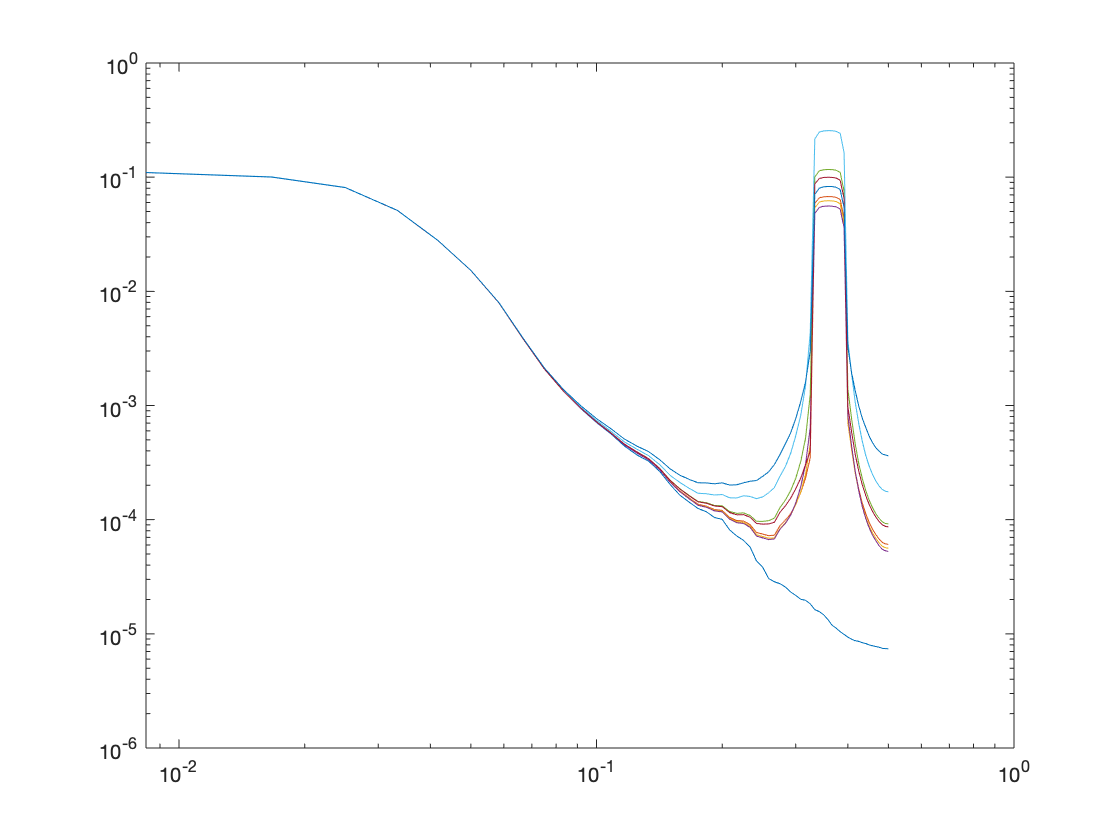

figure, 
loglog(F_orig, nanmean(SPP_orig + SNN_orig,2))
hold all 
loglog(F_orig, nanmean(SPP_space1 + SNN_space1,2))
loglog(F_orig, nanmean(SPP_space2 + SNN_space2,2))
loglog(F_orig, nanmean(SPP_space3 + SNN_space3,2))
loglog(F_orig, nanmean(SPP_space4 + SNN_space4,2))
loglog(F_orig, nanmean(SPP_space5 + SNN_space5,2))
loglog(F_orig, nanmean(SPP_space6 + SNN_space6,2))
loglog(F_orig, nanmean(SPP_space7 + SNN_space7,2))

## Structure Function

S2ll_orig = S2ll_model(mod_sep_orig.sep, dist_bin);

S2ll_time1 = S2ll_model(mod_sep_time1.sep, dist_bin);
S2ll_time2 = S2ll_model(mod_sep_time2.sep, dist_bin);
S2ll_time3 = S2ll_model(mod_sep_time3.sep, dist_bin);
S2ll_time4 = S2ll_model(mod_sep_time4.sep, dist_bin);

S2ll_space1 = S2ll_model(mod_sep_space1.sep, dist_bin);
S2ll_space2 = S2ll_model(mod_sep_space2.sep, dist_bin);
S2ll_space3 = S2ll_model(mod_sep_space3.sep, dist_bin);
S2ll_space4 = S2ll_model(mod_sep_space4.sep, dist_bin);
S2ll_space5 = S2ll_model(mod_sep_space5.sep, dist_bin);
S2ll_space6 = S2ll_model(mod_sep_space6.sep, dist_bin);

S2ll_space7 = S2ll_model(mod_sep_space7.sep, dist_bin);

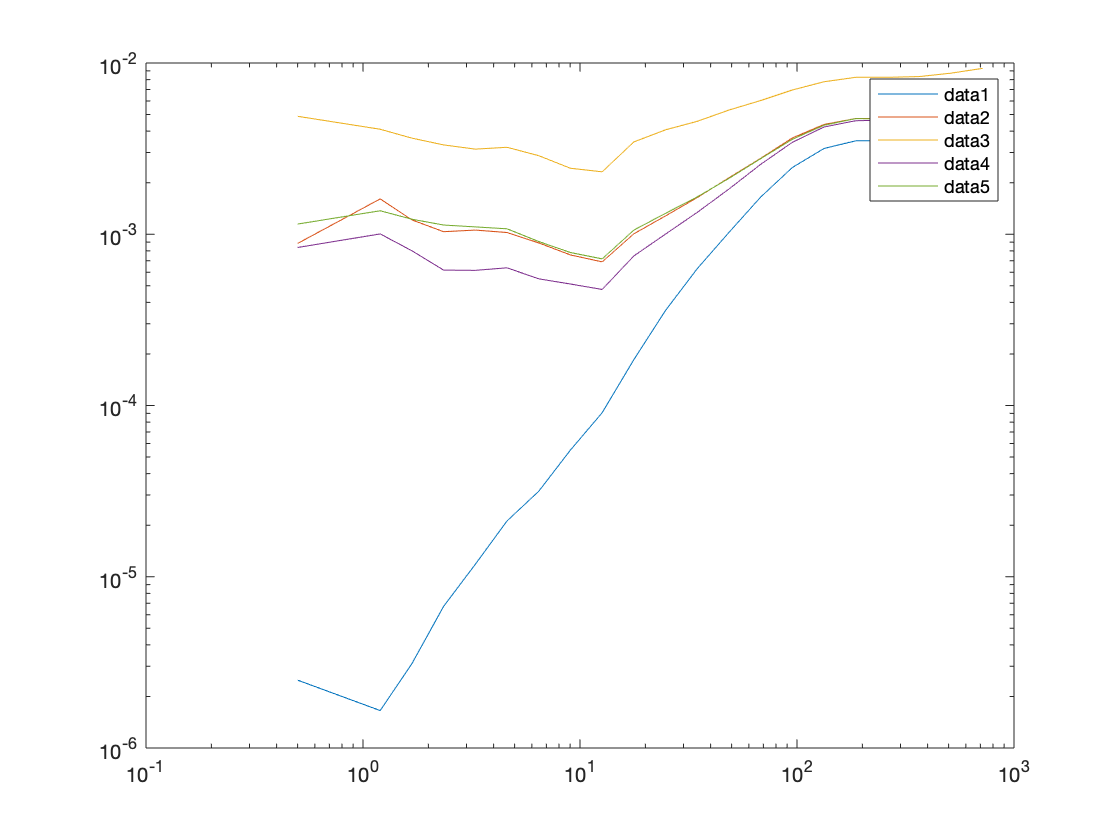

figure,
loglog(dist_axis/1e3, S2ll_orig)
hold all
loglog(dist_axis/1e3, S2ll_time1)
loglog(dist_axis/1e3, S2ll_time2)
loglog(dist_axis/1e3, S2ll_time3)
loglog(dist_axis/1e3, S2ll_time4)
legend

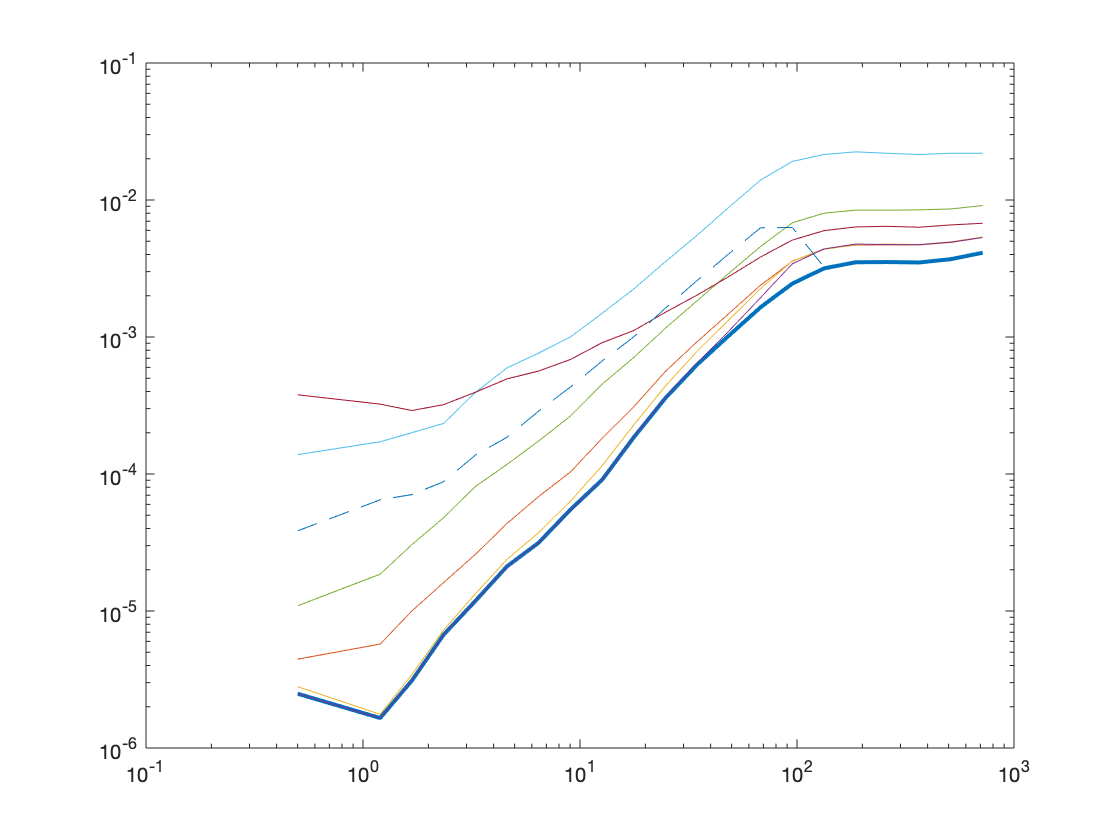

figure,
loglog(dist_axis/1e3, S2ll_orig,'linewidth',2)
hold all
loglog(dist_axis/1e3, S2ll_space1)
loglog(dist_axis/1e3, S2ll_space2)
loglog(dist_axis/1e3, S2ll_space3)
loglog(dist_axis/1e3, S2ll_space4)
loglog(dist_axis/1e3, S2ll_space5)
loglog(dist_axis/1e3, S2ll_space6)
loglog(dist_axis/1e3, S2ll_space7,'--')

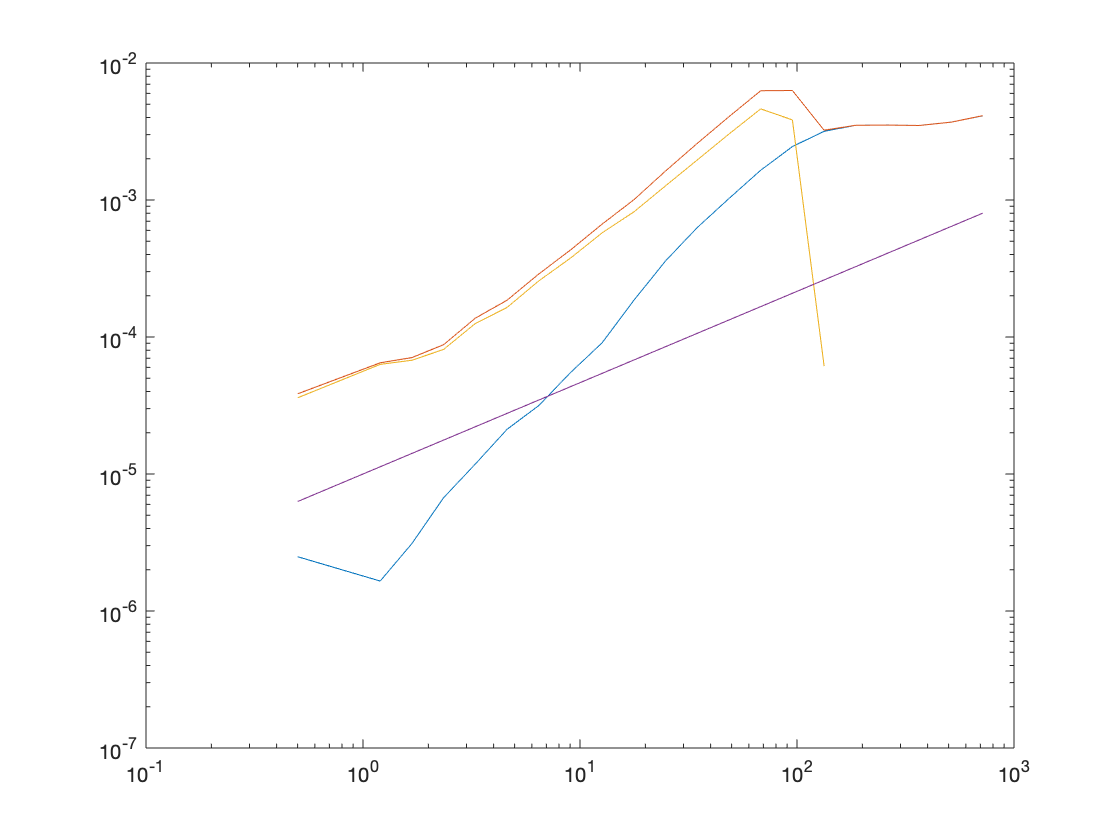

figure, 
loglog(dist_axis/1e3, S2ll_orig)
hold all
loglog(dist_axis/1e3, S2ll_space7)
loglog(dist_axis/1e3, S2ll_space7 - S2ll_orig)

loglog(dist_axis/1e3, 1e-7*dist_axis.^(2/3))

## Dispersion

ndays=100;
disp_orig = rel_disp(mod_sep_orig.sep, ndays);
disporig = disp_orig.avdisp/1e6;


T=[0:99];

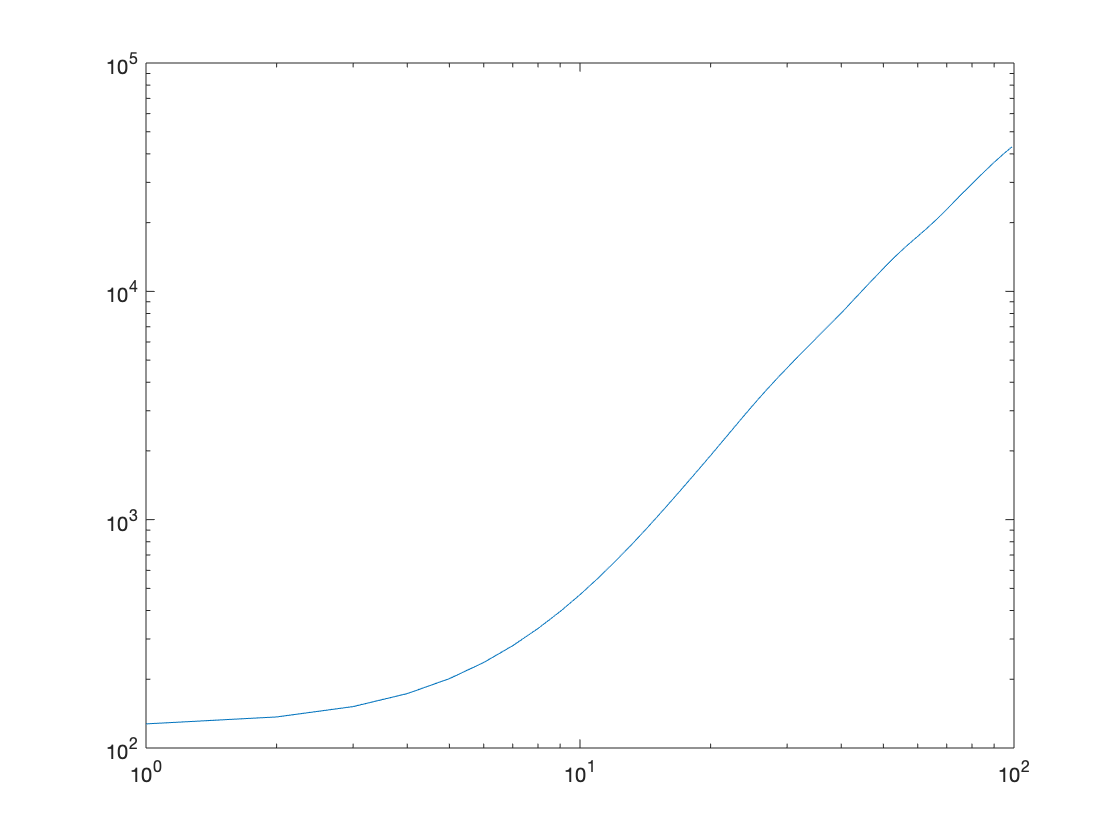

figure,
loglog(T, disporig)

## Relative Diffusivity

%mod_sep_orig_4_rd = model_sep_calcs_w_NIWs(mod_traj, [0,50]*1e3,0,0,0,0,0);
rd_orig_1 = rel_diff_inst_model(mod_sep_orig.sep, dist_bin,1); 
rd_orig_6 = rel_diff_inst_model(mod_sep_orig.sep, dist_bin,6); 

rd_space1_1 = rel_diff_inst_model(mod_sep_space1.sep, dist_bin,1); 
rd_space1_6 = rel_diff_inst_model(mod_sep_space1.sep, dist_bin,6); 
rd_space5_1 = rel_diff_inst_model(mod_sep_space5.sep, dist_bin,1); 
rd_space5_6 = rel_diff_inst_model(mod_sep_space5.sep, dist_bin,6); 

rd_space7_1 = rel_diff_inst_model(mod_sep_space7.sep, dist_bin,1); 
rd_space7_6 = rel_diff_inst_model(mod_sep_space7.sep, dist_bin,6); 

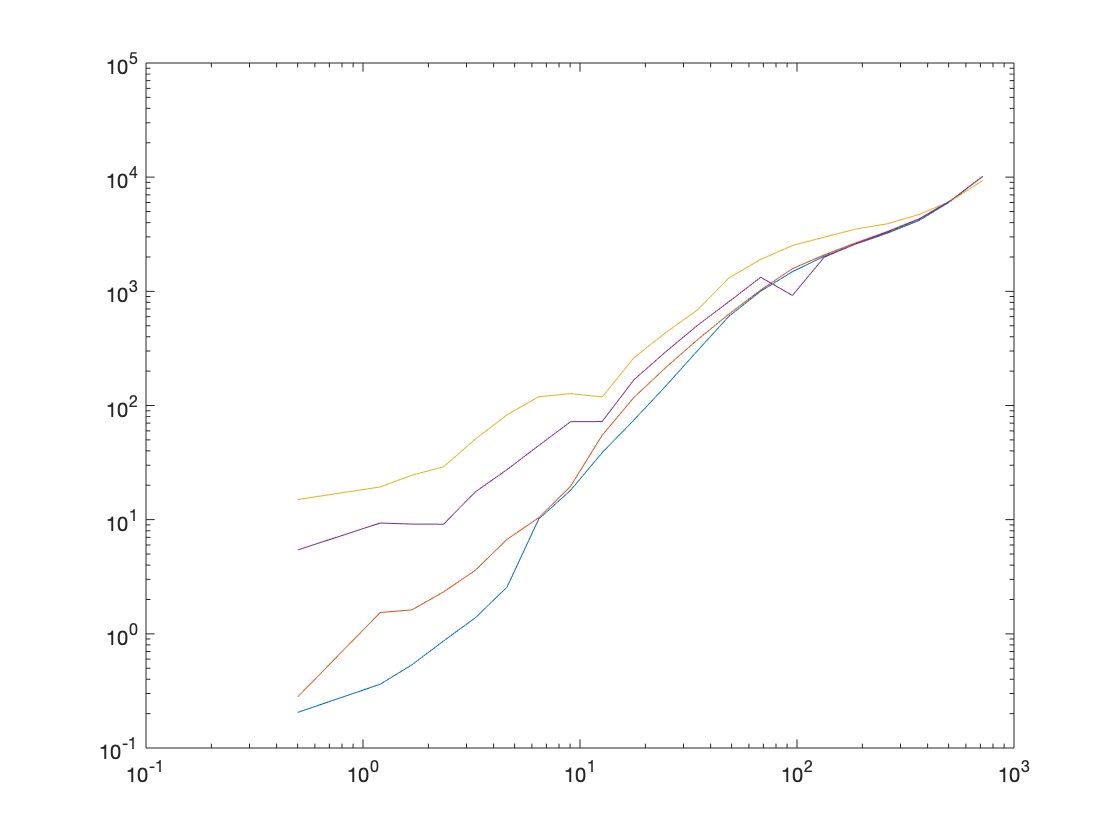

figure, 
loglog(dist_axis/1e3, rd_orig.rdmean)
hold all 
loglog(dist_axis/1e3, rd_space1_1.rdmean)
loglog(dist_axis/1e3, rd_space5_1.rdmean)
loglog(dist_axis/1e3, rd_space7_1.rdmean)

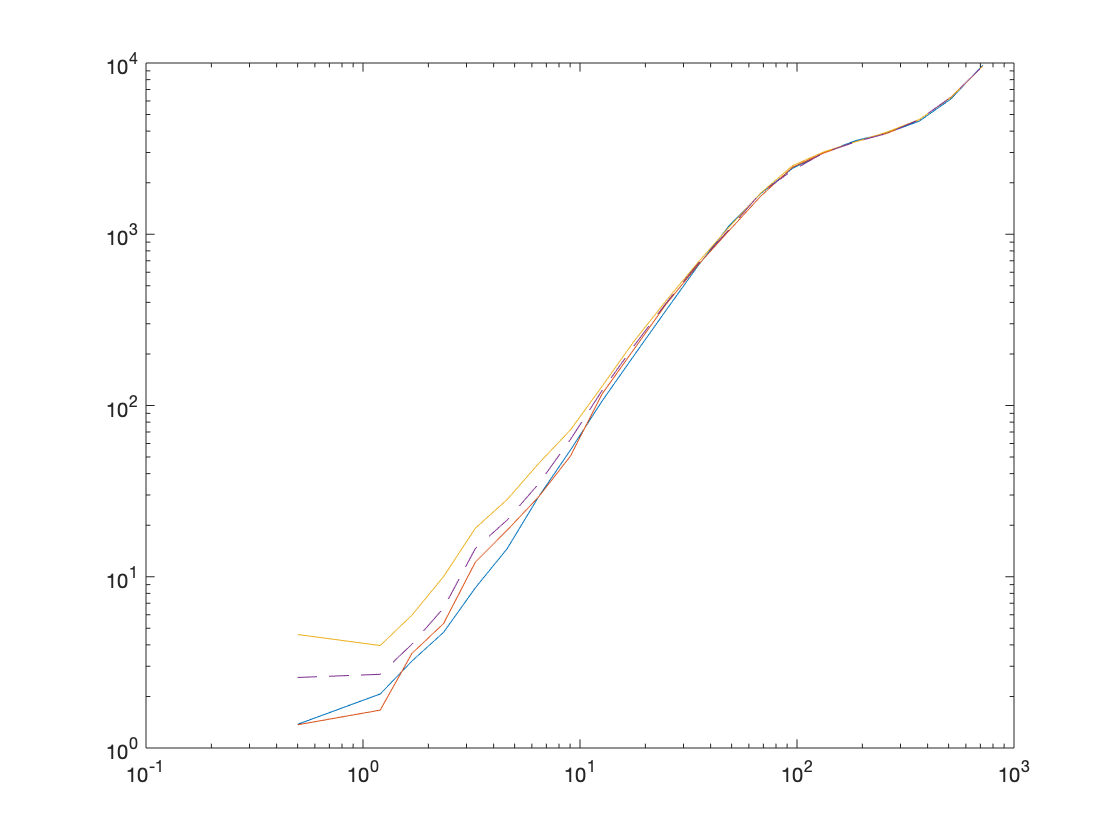

figure, 
loglog(dist_axis/1e3, rd_orig_6.rdmean)
hold all 
loglog(dist_axis/1e3, rd_space1_6.rdmean)
loglog(dist_axis/1e3, rd_space5_6.rdmean)
loglog(dist_axis/1e3, rd_space7_6.rdmean,'--')

## Functions

function [F, SPP, SNN, SPN] = spec_pairs(sep, dT)
len = 120/dT;
psi = sleptap(len);
npairs  = length(sep.sep);
CV = zeros(len, 2*npairs);

n=1;
for i = 1:npairs
    CV(:,n) = sep.sep(i).U1(1:len) + sqrt(-1)*sep.sep(i).V1(1:len);
    n=n+1;
    CV(:,n) = sep.sep(i).U2(1:len) + sqrt(-1)*sep.sep(i).V2(1:len);
    n=n+1;
end

[F, SPP, SNN, SPN] = mspec(dT, CV, psi,'cyclic');

end
